# Given Data

file = unzip('/MATLAB Drive/yalefaces.zip');
df=file(1:90);

## Image Vectors

all_img = zeros(243,320,90);
vectorized_img = zeros(77760,90);
for i = 1:90
    I =imread(df{i});
    all_img(:,:,i) = I;
    vectorized_img(:,i) = reshape(I,1,[]);
end 

## Normal Image Vectors

normal_img_vectors = zeros(77760,15);
for i = 1:15
    normal_img_vectors(:,i) = vectorized_img(:,6*i);
end

## A

cnt=0;
for i = 1:90
    curr_img = vectorized_img(:,i);
    d = Inf;
    index =i; 
    for j = 1 : 15
        v  = curr_img - normal_img_vectors(:,j);
        if d >= norm(v)
            index=j;
            d = norm(v);
        end 
    end 
    % index cross checking 
    if 6*index - i <= 5 && 6*index - i >=0
        fprintf('%d  Yes\n', i);
        cnt = cnt+1;
    else 
        fprintf('%d  No\n', i);
    end
end 

1  Yes
2  Yes
3  Yes


4  No
5  No


6  Yes
7  Yes
8  Yes
9  Yes
10  Yes
11  Yes
12  Yes


13  No


14  Yes
15  Yes


16  No


17  Yes
18  Yes
19  Yes
20  Yes
21  Yes


22  No


23  Yes
24  Yes
25  Yes
26  Yes
27  Yes


28  No


29  Yes
30  Yes


31  No


32  Yes
33  Yes


34  No


35  Yes
36  Yes


37  No


38  Yes
39  Yes


40  No


41  Yes
42  Yes
43  Yes
44  Yes
45  Yes


46  No
47  No


48  Yes


49  No
50  No


51  Yes


52  No


53  Yes
54  Yes


55  No
56  No


57  Yes


58  No


59  Yes
60  Yes
61  Yes
62  Yes
63  Yes
64  Yes
65  Yes
66  Yes


67  No
68  No
69  No


70  Yes
71  Yes
72  Yes


73  No


74  Yes
75  Yes


76  No


77  Yes
78  Yes
79  Yes
80  Yes
81  Yes


82  No


83  Yes
84  Yes
85  Yes


86  No


87  Yes


88  No
89  No


90  Yes


disp(['The normal image classifier :'])

The normal image classifier :


cnt

cnt = 63

## B

pcs = zeros(77760,15)

pcs =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:15
    cd = vectorized_img(:,6*i-5:6*i);
    cd_sf = cd - mean(cd,1);
    c = cov(cd_sf);
    [e v] = eig(c);
    eval = diag(v);
    [~,ind] = sort(eval);
    new_data = cd*e(:,ind(6));
    new_data_rec= rescale(new_data,0,255);
    pcs(:,i) = new_data_rec;
end
pcs

pcs =   115.0706  113.1425  127.5477  129.4189  110.2082  111.6888  127.3599  128.4888  124.6122  128.4148  127.2156  116.4050  127.7468  128.0616  123.2449
  255.0000  239.8999  255.0000  255.0000  253.3127  241.6530  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  252.3990
  255.0000  252.7023  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  251.5270  255.0000  255.0000  250.5449
  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  242.6515  255.0000  255.0000  247.3448
  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  255.0000  251.6715  246.8963  255.0000  255.0000  240.5193
  255.0000  255.0000  255.0000  255.0000  255.0000  249.7864  255.0000  255.0000  255.0000  255.0000  251.1960  255.0000  255.0000  255.0000  240.8992
  255.0000  255.0000  255.0000  255.0000  255.0000  212.5798  255.0000  255.0000  255.00

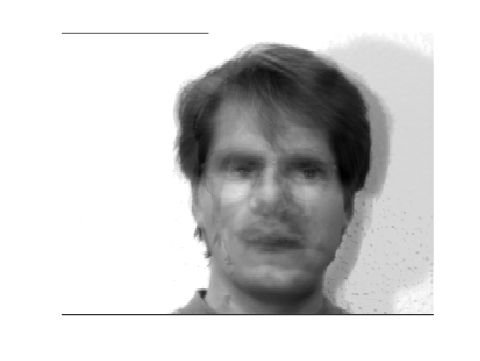

B = reshape(pcs(:,1),[243,320]);
B =uint8(B);
imshow(B)

cnt=0;
idx = zeros(90,1);
for i =1:90
    curr_img = vectorized_img(:,i);
    d = Inf;
    index =i; 
    for j = 1 : 15
        v  = curr_img - pcs(:,j);
        if d >= norm(v)
            index=j;
            d = norm(v);
        end 
    end 
    % index cross checking 
    if 6*index - i <= 5 && 6*index - i >=0
        fprintf('%d  Yes\n', i);
        cnt = cnt+1;
        idx(i)=1;
    else 
        fprintf('%d  No\n', i);
    end
end

1  Yes
2  Yes
3  Yes
4  Yes


5  No


6  Yes
7  Yes
8  Yes
9  Yes
10  Yes
11  Yes
12  Yes
13  Yes
14  Yes
15  Yes


16  No


17  Yes
18  Yes
19  Yes
20  Yes
21  Yes


22  No


23  Yes
24  Yes
25  Yes
26  Yes
27  Yes


28  No


29  Yes
30  Yes


31  No


32  Yes
33  Yes


34  No


35  Yes
36  Yes
37  Yes
38  Yes
39  Yes


40  No


41  Yes
42  Yes
43  Yes
44  Yes
45  Yes


46  No


47  Yes
48  Yes
49  Yes
50  Yes
51  Yes


52  No


53  Yes
54  Yes
55  Yes
56  Yes
57  Yes


58  No


59  Yes
60  Yes
61  Yes
62  Yes
63  Yes
64  Yes
65  Yes
66  Yes


67  No


68  Yes


69  No


70  Yes
71  Yes
72  Yes
73  Yes
74  Yes
75  Yes


76  No


77  Yes
78  Yes
79  Yes
80  Yes
81  Yes
82  Yes
83  Yes
84  Yes
85  Yes
86  Yes
87  Yes


88  No


89  Yes
90  Yes


disp(['Classification with 1 rep. image :'])

Classification with 1 rep. image :


cnt

cnt = 76

## C

pcs2  = zeros(77760,15);
for i = 1:15
    cd = vectorized_img(:,6*i-5:6*i);
    cd_sf = cd - mean(cd,1);
    c = cov(cd_sf);
    [e v] = eig(c);
    eval = diag(v);
    [~,ind] = sort(eval);
    new_data = cd*(e(:,ind(5))+ e(:,ind(6)));
    new_data_rec= rescale(new_data,0,255);
    pcs2(:,i) = new_data_rec;
end
pcs2

pcs2 =    96.3478  109.0976  122.3422  118.8471   93.6104  113.5731  112.8257  112.0121  116.9787  124.1798  102.6835  127.1950  113.5439  109.6908  124.0981
  217.8103  206.1546  215.1518  211.0361  208.9911  173.9626  206.1240  202.1891  210.9512  223.2100  207.9211  234.5964  219.0590  209.1823  218.4936
  217.8103  220.5893  215.1518  211.0361  211.0081  185.7797  206.1240  202.1891  210.9512  223.2100  207.9211  229.4523  219.0590  209.1823  217.1896
  217.8103  223.1495  215.1518  211.0361  211.0081  185.7797  206.1240  202.1891  210.9512  223.2100  207.9211  216.3061  219.0590  209.1823  217.0803
  217.8103  223.1495  215.1518  211.0361  211.0081  185.7797  206.1240  202.1891  210.9512  223.2100  211.9399  222.5934  219.0590  209.1823  216.2006
  217.8103  223.1495  215.1518  211.0361  211.0081  181.1593  206.1240  202.1891  210.9512  223.2100  212.5140  234.5964  219.0590  209.1823  216.5281
  217.8103  223.1495  215.1518  211.0361  211.0081  148.4990  206.1240  202.1891  210.9

pcs2

pcs2 =    96.3478  109.0976  122.3422  118.8471   93.6104  113.5731  112.8257  112.0121  116.9787  124.1798  102.6835  127.1950  113.5439  109.6908  124.0981
  217.8103  206.1546  215.1518  211.0361  208.9911  173.9626  206.1240  202.1891  210.9512  223.2100  207.9211  234.5964  219.0590  209.1823  218.4936
  217.8103  220.5893  215.1518  211.0361  211.0081  185.7797  206.1240  202.1891  210.9512  223.2100  207.9211  229.4523  219.0590  209.1823  217.1896
  217.8103  223.1495  215.1518  211.0361  211.0081  185.7797  206.1240  202.1891  210.9512  223.2100  207.9211  216.3061  219.0590  209.1823  217.0803
  217.8103  223.1495  215.1518  211.0361  211.0081  185.7797  206.1240  202.1891  210.9512  223.2100  211.9399  222.5934  219.0590  209.1823  216.2006
  217.8103  223.1495  215.1518  211.0361  211.0081  181.1593  206.1240  202.1891  210.9512  223.2100  212.5140  234.5964  219.0590  209.1823  216.5281
  217.8103  223.1495  215.1518  211.0361  211.0081  148.4990  206.1240  202.1891  210.9

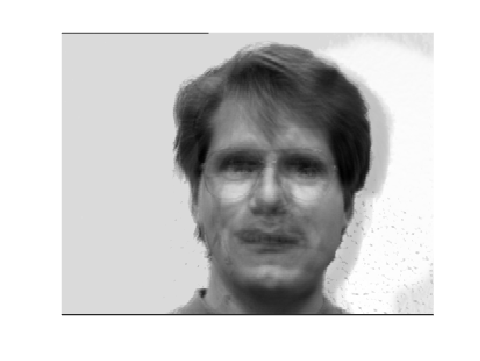

B = reshape(pcs2(:,1),[243,320]);
B =uint8(B);
imshow(B)

cnt=0;
for i = 1:90
    curr_img = vectorized_img(:,i);
    d = Inf;
    index =i; 
    for j = 1 : 15
        v = curr_img - pcs2(:,j);
        if d >= norm(v)
            index=j;
            d = norm(v);
        end 
    end 
    % index cross checking 
    if 6*index - i <= 5 && 6*index - i >=0
        fprintf('%d  Yes\n', i);
        cnt = cnt+1;
        idx(i)=1;
    else 
        fprintf('%d  No\n', i);
    end
end

1  Yes
2  Yes
3  Yes


4  No
5  No


6  Yes
7  Yes
8  Yes
9  Yes


10  No


11  Yes
12  Yes


13  No


14  Yes
15  Yes


16  No


17  Yes
18  Yes
19  Yes
20  Yes
21  Yes


22  No


23  Yes
24  Yes
25  Yes
26  Yes
27  Yes


28  No


29  Yes
30  Yes


31  No


32  Yes
33  Yes


34  No


35  Yes
36  Yes


37  No


38  Yes
39  Yes


40  No


41  Yes
42  Yes
43  Yes
44  Yes
45  Yes


46  No
47  No


48  Yes


49  No
50  No


51  Yes


52  No


53  Yes
54  Yes


55  No
56  No


57  Yes


58  No


59  Yes
60  Yes
61  Yes
62  Yes
63  Yes
64  Yes
65  Yes
66  Yes


67  No
68  No
69  No


70  Yes
71  Yes
72  Yes
73  Yes
74  Yes
75  Yes


76  No


77  Yes
78  Yes
79  Yes
80  Yes
81  Yes


82  No


83  Yes
84  Yes
85  Yes
86  Yes
87  Yes


88  No


89  Yes


90  No


disp(['Classification with 2 rep. images : '])

Classification with 2 rep. images : 


cnt

cnt = 64

cnt_t=0;
for i=1:90
    if idx(i) == 1
        cnt_t = cnt_t+1;
    end
end
disp(['Unique classfications :'])

Unique classfications :


cnt_t

cnt_t = 76

Conclusion: In this question increasing the number of principal components does not necessarily mean that we will be able to classify more images correctly because effectively, we are obtaining a resultant image from 6 images belonging to a subject. This can improve the classification of one image as well and can reduce the classification accuracy of another image, as the number of principal components increases.